# Individual Assignment - Image Processing Fundamentals

**Option C: Compare edge detectors**

The experiment compares the number and appearance of edges in a clean grayscale image and a Gaussian-noisy version. It uses one Sobel method (after Gaussian smoothing) and two Canny settings. All image processing parameters are fixed by the assignment.

## 1. Input image and experimental setup

The input is MATLAB's built-in `cameraman.tif` test image, supplied with Image Processing Toolbox. The original image is not included in the repository. `rng(42)` makes the noise reproducible within the same MATLAB environment.

I = imread('cameraman.tif');
assert(ndims(I) == 2, 'Expected a grayscale cameraman image.');
rng(42);
In = imnoise(I,'gaussian',0,0.01);
resultsDir = 'results';
if ~exist(resultsDir,'dir')
    mkdir(resultsDir);
end
imageSize = size(I);
fprintf('Input: cameraman.tif, size %d x %d\n', imageSize(1), imageSize(2));

Input: cameraman.tif, size 256 x 256


disp(['MATLAB version: ',version]);

MATLAB version: 25.2.0.3123386 (R2025b) Update 3


imageToolboxInfo = ver('images');
if ~isempty(imageToolboxInfo)
    disp(['Image Processing Toolbox version: ',imageToolboxInfo.Version]);
end

Image Processing Toolbox version: 25.2


fid = fopen(fullfile(resultsDir,'matlab_version.txt'),'w');
if fid ~= -1
    fprintf(fid,'MATLAB: %s\n',version);
    if ~isempty(imageToolboxInfo)
        fprintf(fid,'Image Processing Toolbox: %s\n', ...
            imageToolboxInfo.Version);
    end
    fclose(fid);
end

## 2. Three methods applied to the clean and noisy images

**Sobel:** Smooth each image with `imgaussfilt(...,1)` first, then use the default Sobel edge threshold. **Canny 1:** Default automatic threshold, sigma 1. **Canny 3:** The same automatic threshold rule, sigma 3. No custom thresholds, postprocessing, or changed noise settings are used.

E_clean_sobel = edge(imgaussfilt(I,1),'Sobel');
E_clean_canny1 = edge(I,'Canny',[],1);
E_clean_canny3 = edge(I,'Canny',[],3);
E_noisy_sobel = edge(imgaussfilt(In,1),'Sobel');
E_noisy_canny1 = edge(In,'Canny',[],1);
E_noisy_canny3 = edge(In,'Canny',[],3);

## 3. Show all six edge maps in one figure

The top row uses the clean image. The bottom row repeats exactly the same three edge-detector settings on the noisy image. White pixels represent detected edges.

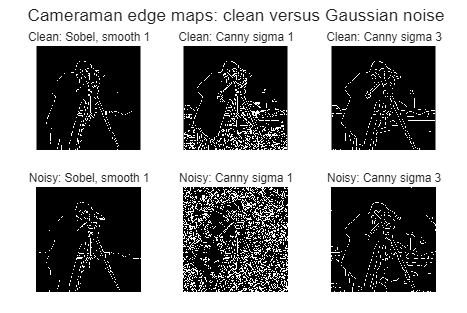

edgeFigure = figure(Theme='light', Position=[100 100 760 510]);
t = tiledlayout(edgeFigure,2,3,'Padding','compact','TileSpacing','compact');
nexttile; imshow(E_clean_sobel);  title('Clean: Sobel, smooth 1');
nexttile; imshow(E_clean_canny1); title('Clean: Canny sigma 1');
nexttile; imshow(E_clean_canny3); title('Clean: Canny sigma 3');
nexttile; imshow(E_noisy_sobel);  title('Noisy: Sobel, smooth 1');
nexttile; imshow(E_noisy_canny1); title('Noisy: Canny sigma 1');
nexttile; imshow(E_noisy_canny3); title('Noisy: Canny sigma 3');
title(t,'Cameraman edge maps: clean versus Gaussian noise');
exportgraphics(t,fullfile(resultsDir,'edge_maps.png'),'Resolution',200);

## 4. Edge-pixel counts

`nnz` counts white (true) pixels in each binary edge map. The two input images have identical dimensions, so direct pixel-count comparison is valid. However, a larger count does **not** mean better detection.

Image = {'Clean';'Noisy'};
Sobel_after_Gaussian1 = [nnz(E_clean_sobel);nnz(E_noisy_sobel)];
Canny_sigma1 = [nnz(E_clean_canny1);nnz(E_noisy_canny1)];
Canny_sigma3 = [nnz(E_clean_canny3);nnz(E_noisy_canny3)];
countsTable = table(Image,Sobel_after_Gaussian1,Canny_sigma1,Canny_sigma3);
disp(countsTable);

      Image      Sobel_after_Gaussian1    Canny_sigma1    Canny_sigma3
    _________    _____________________    ____________    ____________

    {'Clean'}            2099                 7816            2780    
    {'Noisy'}            2026                18112            3184    



writetable(countsTable,fullfile(resultsDir,'edge_counts.csv'));
method = {'Sobel+Gaussian 1';'Canny sigma 1';'Canny sigma 3'};
CleanEdges = [nnz(E_clean_sobel);nnz(E_clean_canny1);nnz(E_clean_canny3)];
NoisyEdges = [nnz(E_noisy_sobel);nnz(E_noisy_canny1);nnz(E_noisy_canny3)];
NoisyOnlyEdges = [nnz(E_noisy_sobel & ~E_clean_sobel);
    nnz(E_noisy_canny1 & ~E_clean_canny1);
    nnz(E_noisy_canny3 & ~E_clean_canny3)];
CleanOnlyEdges = [nnz(E_clean_sobel & ~E_noisy_sobel);
    nnz(E_clean_canny1 & ~E_noisy_canny1);
    nnz(E_clean_canny3 & ~E_noisy_canny3)];
comparisonTable = table(method,CleanEdges,NoisyEdges, ...
    NoisyOnlyEdges,CleanOnlyEdges);
disp(comparisonTable);

           method           CleanEdges    NoisyEdges    NoisyOnlyEdges    CleanOnlyEdges
    ____________________    __________    __________    ______________    ______________

    {'Sobel+Gaussian 1'}       2099          2026             298               371     
    {'Canny sigma 1'   }       7816         18112           13096              2800     
    {'Canny sigma 3'   }       2780          3184            1010               606     



writetable(comparisonTable,fullfile(resultsDir,'edge_comparison.csv'));

## 5. Visualise the count comparison

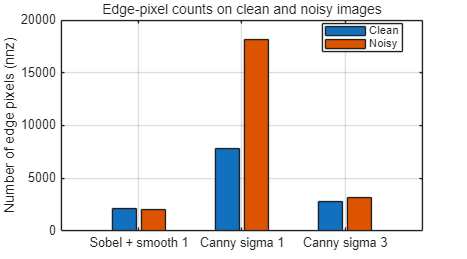

x = categorical({'Sobel + smooth 1','Canny sigma 1','Canny sigma 3'});
x = reordercats(x,{'Sobel + smooth 1','Canny sigma 1','Canny sigma 3'});
countFigure = figure(Theme='light', Position=[100 100 650 360]);
countAxes = axes(countFigure);
bar(countAxes,x,[CleanEdges,NoisyEdges],'grouped');
ylabel('Number of edge pixels (nnz)');
title('Edge-pixel counts on clean and noisy images');
legend({'Clean','Noisy'},'Location','best');
grid on;
countAxes.YAxis.Exponent = 0;
exportgraphics(countAxes,fullfile(resultsDir,'edge_pixel_counts.png'), ...
    'Resolution',200);

## 6. Inspect the upper-right sky

Rows 20-65 and columns 165-225 cover a smooth patch of sky above the buildings. C1 and C3 indicate Canny sigma 1 and 3. In this crop, Canny sigma 1 goes from 0 marked pixels on the clean image to 916 on the noisy image. Many short fragments appear without a corresponding scene boundary. Noisy Canny sigma 3 and smoothed Sobel both mark 0 pixels in the same crop.

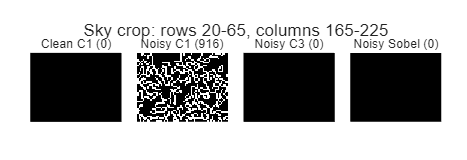

rows = 20:65;
cols = 165:225;
cleanSky = E_clean_canny1(rows,cols);
noisySky1 = E_noisy_canny1(rows,cols);
noisySky3 = E_noisy_canny3(rows,cols);
noisySkySobel = E_noisy_sobel(rows,cols);
regionFigure = figure(Theme='light', Position=[100 100 760 260]);
tRegion = tiledlayout(regionFigure,1,4, ...
    'Padding','compact','TileSpacing','compact');
nexttile; imshow(cleanSky); title(sprintf('Clean C1 (%d)',nnz(cleanSky)));
nexttile; imshow(noisySky1); title(sprintf('Noisy C1 (%d)',nnz(noisySky1)));
nexttile; imshow(noisySky3); title(sprintf('Noisy C3 (%d)',nnz(noisySky3)));
nexttile; imshow(noisySkySobel);
title(sprintf('Noisy Sobel (%d)',nnz(noisySkySobel)));
title(tRegion,'Sky crop: rows 20-65, columns 165-225');
exportgraphics(tRegion,fullfile(resultsDir,'region_inspection.png'), ...
    'Resolution',220);

## 7. Discussion and interpretation

Noise increased Canny sigma 1 from 7,816 to 18,112 edge pixels. At sigma 3, the noisy map had 3,184 edge pixels and retained the main silhouette and tripod. Stronger Gaussian smoothing attenuates short-scale intensity fluctuations before gradients are computed. MATLAB chooses thresholds automatically for each run, so the comparison includes how the default threshold rule responds to the smoothed image.

Gaussian pre-smoothing also attenuates the pixel-scale fluctuations passed to Sobel. Its map stayed sparse, changing from 2,099 to 2,026 pixels. This experiment compares the specified configurations. Measuring the isolated effect of Sobel pre-smoothing would require an additional unsmoothed Sobel run.

Canny sigma 3 is the preferred Canny setting for a coarse outline on this noisy image. The clean sigma 1 map preserves more fine background texture, including short lines in the grass to the right of the tripod. Many are absent from the clean sigma 3 map, illustrating the cost of stronger smoothing.

**Limitation:** `nnz` counts marked pixels. Accuracy requires annotated boundaries. Even when a detector finds the same physical boundary, a small shift of its detected position can create both clean-only and noisy-only pixels. The experiment covers one image and one fixed noise realization.

## 8. Conclusion

Increasing Canny sigma from 1 to 3 removed much of the noise-driven clutter in the sky and retained the major outlines. The stronger smoothing also reduced detail in the textured background. The selected scale should reflect which boundaries matter for the task.